# Suprod

## from [http://jonova.s3.amazonaws.com/cfa/optimal-fourier-transform.pdf](http://jonova.s3.amazonaws.com/cfa/optimal-fourier-transform.pdf)

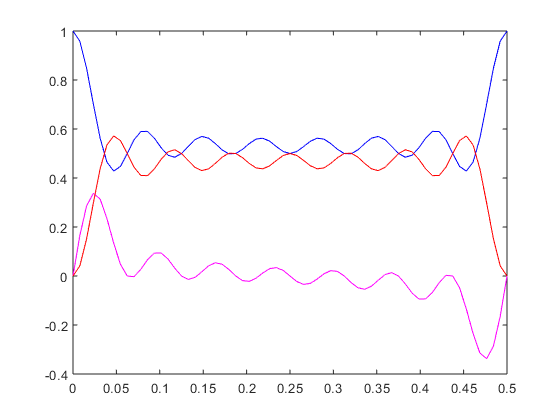

clear all
N = 8;

for n = 0:N^2
    u = n/N/2;
    nuN(n+1)=u/N;
    v = u;
    [a]=cc(v,u,N);
    CC(n+1)=a;
    [a]=cs(v,u,N);
    CS(n+1)=a;
    [a]=ss(v,u,N);
    SS(n+1)=a;
end

figure
plot(nuN,CC,'b',nuN,CS,'m',nuN,SS,'r')

# Functions

## CCn

function [CCn] = cc(v,u,N)
CCn=0;
for tau = 0:N-1    
        CCn = CCn+cos(2*pi*v*tau/N)*cos(2*pi*u*tau/N);   
end
CCn = CCn/N;
end

## CSn

function [CSn] = cs(v,u,N)
CSn=0;
for tau = 0:N-1    
        CSn = CSn+cos(2*pi*v*tau/N)*sin(2*pi*u*tau/N);   
end
CSn = CSn/N;
end

## SSn

function [SSn] = ss(v,u,N)
SSn=0;
for tau = 0:N-1    
        SSn = SSn+sin(2*pi*v*tau/N)*sin(2*pi*u*tau/N);   
end
SSn = SSn/N;
end